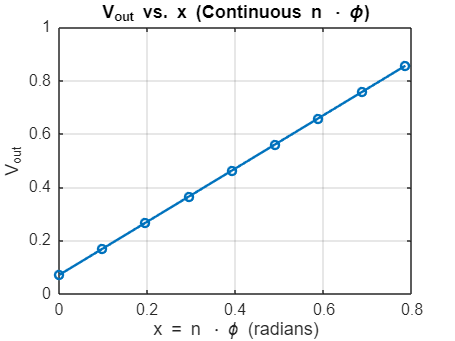

clear; clc;


phi = pi / 32; 

V_neg1 = cos(1.5 - phi);
V_0 = cos(1.5);
V_1 = cos(1.5 + phi);

ABk = 2*(V_1 - V_0) / phi;

delta_theta = pi/2 - (2 * V_0 / ABk);


x_values = (0:8) * pi/32; 
Vout_values = zeros(size(x_values)); 


for i = 1:length(x_values)
    x = x_values(i);
    Vout_values(i) = - (ABk / 2) * (delta_theta + x - pi / 2);
end


figure;
plot(x_values, Vout_values, '-o', 'LineWidth', 1.5, 'MarkerSize', 5);


xlabel('x = n \cdot \phi (radians)');
ylabel('V_{out}');
title('V_{out} vs. x (Continuous n \cdot \phi)');
grid on;